% Find the center of gravity
% y=x^2, y=2*x^2, x=1, x=2

syms x y;
y1=x^2

$$y1 = x^{2}$$

y2=2*x^2

$$y2 = 2\,x^{2}$$

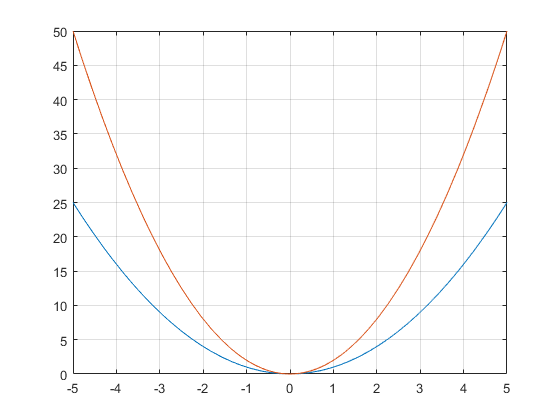

fplot(y1)
hold on
fplot(y2)
hold off
grid on


S=int(int(1,y,y1,y2),x,1,2)

$$S = \frac{7}{3}$$

xm=1/S*int(int(x,y,y1,y2),x,1,2)

$$xm = \frac{45}{28}$$

% 45/28
ym=1/S*int(int(y,y,y1,y2),x,1,2)

$$ym = \frac{279}{70}$$

% 279/70

% #82
% Find the center of gravity
% rho=a*(1+cos(theta))
% x=rho*cos(theta)
% y=rho*sin(theta)

syms a theta rho;
% rho1=1+cos(theta)

% ezpolar(rho1)
% grid on

S=int(int(rho,rho,0,a*(1+cos(theta))),theta,0,2*pi)

$$S = \frac{3\,\pi \,a^{2}}{2}$$

% (3*pi*a^2)/2
xm=1/S*int(int(rho*rho*cos(theta),rho,0,a*(1+cos(theta))),theta,0,2*pi)

$$xm = \frac{5\,a}{6}$$

% (5*a)/6
ym=1/S*int(int(rho*rho*sin(theta),rho,0,a*(1+cos(theta))),theta,0,2*pi)

$$ym = 0$$

% 0

% #83
% Find the center of gravity
% y^2=a*x, x=a, y=0

syms y x;

S=int(int(1,x,y^2/a,a),y,0,a)

$$S = \frac{2\,a^{2}}{3}$$

% (2*a^2)/3
xm=1/S*int(int(x,x,y^2/a,a),y,0,a)

$$xm = \frac{3\,a}{5}$$

% (3*a)/5
ym=1/S*int(int(y,x,y^2/a,a),y,0,a)

$$ym = \frac{3\,a}{8}$$

% (3*a)/8

% #84
% Find the center of gravity
% rho=a*sin(2*theta)

syms a theta rho;
rho1=sin(2*theta)

$$rho1 = \sin\left(2\,\theta \right)$$

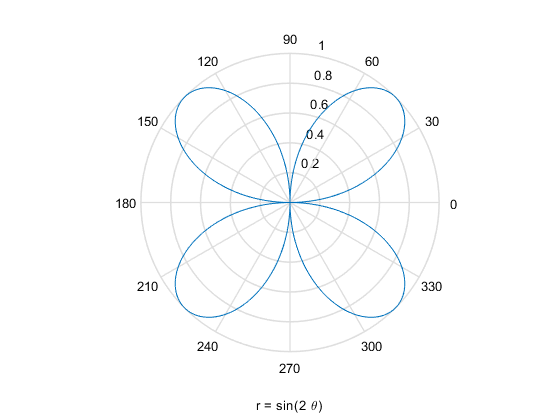

ezpolar(rho1)

S=int(int(rho,rho,0,a*sin(2*theta)),theta,0,pi/2)

$$S = \frac{\pi \,a^{2}}{8}$$

% (pi*a^2)/8
xm=1/S*int(int(rho*rho*cos(theta),rho,0,a*sin(2*theta)),theta,0,pi/2)

$$xm = \frac{128\,a}{105\,\pi }$$

% (128*a)/(105*pi)
ym=1/S*int(int(rho*rho*sin(theta),rho,0,a*sin(2*theta)),theta,0,pi/2)

$$ym = \frac{128\,a}{105\,\pi }$$

% (128*a)/(105*pi)

% #85
% Find the center of gravity
% y^2=x, x^2=y

syms x y;
y1=x^2

$$y1 = x^{2}$$

y2=sqrt(x)

$$y2 = \sqrt{x}$$

S=int(int(1,y,y1,y2),x,0,1)

$$S = \frac{1}{3}$$

% 1/3
xm=1/S*int(int(x,y,y1,y2),x,0,1)

$$xm = \frac{9}{20}$$

% 9/20
ym=1/S*int(int(y,y,y1,y2),x,0,1)

$$ym = \frac{9}{20}$$

% 9/20

% #86
% Find the center of gravity
% y^2=2*p*x, x=2*p

syms x y p;
x1=2*p

$$x1 = 2\,p$$

x2=y^2/(2*p)

$$x2 = \frac{y^{2}}{2\,p}$$

S=int(int(1,x,x2,x1),y,-2*p,2*p)

$$S = \frac{16\,p^{2}}{3}$$

% (16*p^2)/3
xm=1/S*int(int(x,x,x2,x1),y,-2*p,2*p)

$$xm = \frac{6\,p}{5}$$

% (6*p)/5
ym=1/S*int(int(y,x,x2,x1),y,-2*p,2*p)

$$ym = 0$$

% 0

% #87
% Find the center of gravity
% y=sqrt(2*x-x^2), y=0

syms x y;
y1=sqrt(2*x-x^2)

$$y1 = \sqrt{2\,x-x^{2}}$$

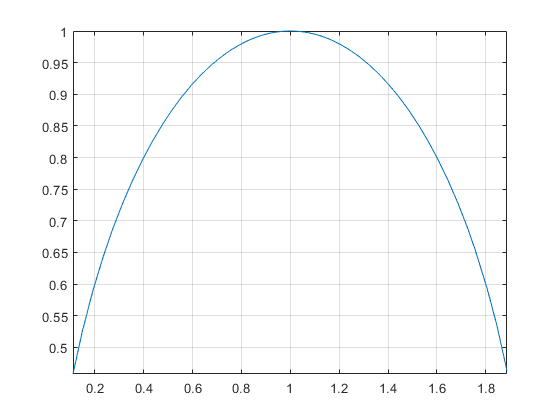

fplot(y1)
grid on


S=int(int(1,y,0,sqrt(2*x-x^2)),x,0,2)

$$S = \frac{\pi }{2}$$

% pi/2
xm=1/S*int(int(x,y,0,sqrt(2*x-x^2)),x,0,2)

$$xm = 1$$

% 1
ym=1/S*int(int(y,y,0,sqrt(2*x-x^2)),x,0,2)

$$ym = \frac{4}{3\,\pi }$$

% 4/(3*pi)

% #88
% Calculate the moment of inertia
% y=2*sqrt(x), x+y=3, x=0, y=0

syms x y;
y1=2*sqrt(x)

$$y1 = 2\,\sqrt{x}$$

y2=3-x

$$y2 = 3-x$$

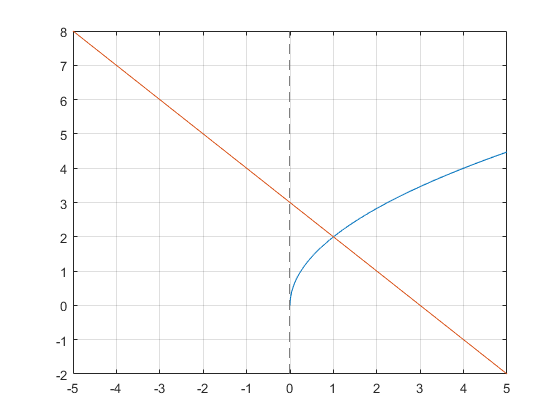

fplot(y1)
hold on
fplot(y2)
hold off
grid on

x1=(y/2)^2

$$x1 = \frac{y^{2}}{4}$$

x2=3-y

$$x2 = 3-y$$


slv=solve(y==2*sqrt(x), x+y==3)

slv = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]


[slv.x slv.y]

$$ans = \left(\begin{array}{cc} 1 & 2 \end{array}\right)$$

% [ 1, 2]
Ix=int(int(y^2,x,x1,x2),y,0,2)

$$Ix = \frac{12}{5}$$

vpa(Ix)

$$ans = 2.4$$

% 2.4
Iy=int(int(x^2,x,x1,x2),y,0,2)

$$Iy = \frac{46}{7}$$

digits(4)
vpa(Iy)

$$ans = 6.571$$

% 6.57

% #89
% Calculate the polar moment of inertia
% x+y=2, x=0, y=0

syms x y;
y1=2-x

$$y1 = 2-x$$

I0=int(int(x^2+y^2,y,0,y1),x,0,2)

$$I0 = \frac{8}{3}$$

% 8/3

% #90
% Calculate the moment of inertia frhom Ox
% y=4-x^2, y=0

syms x y;
y1=4-x^2

$$y1 = 4-x^{2}$$

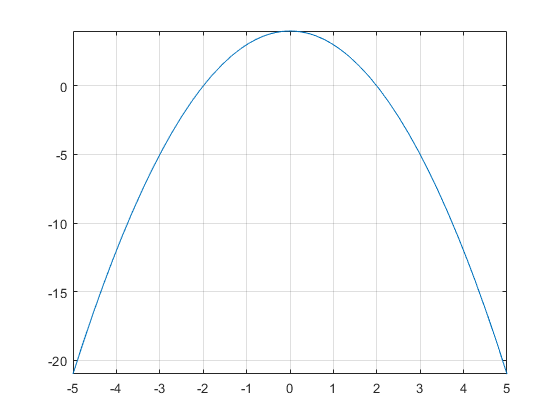

fplot(y1)
grid on

Ix=int(int(y^2,y,0,y1),x,-2,2)

$$Ix = \frac{4096}{105}$$

% 4096/105

% #91
% Calculate the moment of inertia of the ellipse
% x^2/a^2+y^2/b^2=1

syms x y a b;
y1=b*sqrt(1-x^2/a^2)

$$y1 = b\,\sqrt{1-\frac{x^{2}}{a^{2}}}$$


Ix=simplify(int(int(y^2,y,-y1,y1),x,-a,a))

$$Ix = \frac{2\,b^{3}\,\int_{-a}^{a}{\left(a^{2}-x^{2}\right)}^{3/2}\mathrm{d}x}{3\,{\left(a^{2}\right)}^{3/2}}$$

% (pi*a*b^3)/4

% #92
% Calculate the mass of a square plate with side a
syms x y k a;
% plate density
gam=k*(x^2+y^2)

$$gam = k\,\left(x^{2}+y^{2}\right)$$


M=int(int(k*(x^2+y^2),x,0,a),y,0,a)

$$M = \frac{2\,a^{4}\,k}{3}$$

% (2*a^4*k)/3

% #93
% Calculate the mass of a circular plate of radius r
% gam=delta*r/rho

syms rho theta r delta;
M=int(int(delta*r,rho,0,r),theta, 0, 2*pi)

$$M = 2\,\pi \,\delta \,r^{2}$$

% 2*pi*delta*r^2

% #94
% Calculate the static moment of the plate

syms x y a b;
gam=y

$$gam = y$$

y1=b*(1-x/a)

$$y1 = -b\,\left(\frac{x}{a}-1\right)$$


Mx=int(int(y*y,y,0,y1),x,0,a)

$$Mx = \frac{a\,b^{3}}{12}$$

% (a*b^3)/12